# Detection and Visualization of CO2 Concentration Using Hyperspectral Satellite Data

This project focuses on processing satellite hyperspectral data to detect areas with high concentrations of CO₂ and visualizing this information on a world map. This involves using the Hyperspectral Imaging Library for Image Processing Toolbox™ and the Mapping Toolbox™ in MATLAB. The goal is to explore advanced techniques for detecting CO₂ concentrations and potentially other gases, followed by visualizing the results with geospatial information.

## Description:

The task involves several key steps:

- Data Acquisition: Downloading hyperspectral datasets from sources like Landsat or AVIRIS.

- Data Preprocessing: Utilizing the hypercube function in MATLAB to load the data and perform necessary preprocessing steps such as noise reduction and atmospheric correction.

- CO₂ Detection: Implementing algorithms to quantify CO₂ levels using techniques such as:

- Cluster-Tuned Matched Filter (CTMF): This includes clustering similar spectral properties, designing matched filters for each cluster, and applying these filters to detect CO₂ anomalies.

- Result Analysis: Analyzing the final estimates to quantify CO₂ concentrations and identify regions with elevated levels.

- Visualization: Using the Mapping Toolbox to visualize detected CO₂ concentrations on a world map.

## Answer

The answer provides a detailed step-by-step breakdown of the MATLAB script used for processing hyperspectral data, including:

- Clearing the workspace and command window.

- Loading hyperspectral data into a structure.

- Identifying relevant fields containing hyperspectral data and wavelength information.

- Creating a hypercube object to store spectral data.

- Normalizing reflectance values by removing background variations.

- Calculating spectral indices for analyzing gas concentrations.

- Implementing matching algorithms to detect CO₂ absorption bands.

- Extracting and visualizing these bands using appropriate colormaps.

- Estimating CO₂ concentrations using a defined formula.

- Saving processed images for future reference.

- Displaying a completion message at the end of processing.

%% Clear Workspace and Command Window
clear;  % Clears all variables from the workspace, ensuring no previous data is loaded
clc;    % Clears the command window to remove any previous output
disp("Workspace and command window cleared.");  % Display a message indicating that the workspace and command window have been cleared

Workspace and command window cleared.


Hyperspectral Data Cube: The three-dimensional array containing spectral information collected at many wavelengths across a given area. Each pixel corresponds to a spectrum.

- Example: If you have a hyperspectral image of a forest, each pixel in the cube represents reflectance values at multiple wavelengths (e.g., from 400 nm to 2500 nm) for that specific point in the forest.

Wavelength Data: A one-dimensional array that lists the specific wavelengths at which the hyperspectral data was collected.

- Example: An array like [400, 410, 420, ..., 2500] nm represents the wavelengths captured in the hyperspectral image.

%% Load Hyperspectral Data from .mat File
dataFile = 'f110712t01p00r18rdn_c_sc01_ort_img.mat';  % Define the name of the .mat file containing hyperspectral data
dataStruct = load(dataFile);  % Load the data from the .mat file into a structure named 'dataStruct'

% Display available fields in the loaded .mat file
disp('Fields in the loaded .mat file:');

Fields in the loaded .mat file:


disp(fieldnames(dataStruct));  % Display the names of all fields in the loaded .mat file

    {'Image'     }
    {'Wavelength'}




%% Create a Hypercube Object
% Dynamically identify the hyperspectral data field and wavelengths from the loaded data
fieldNames = fieldnames(dataStruct);  % Get the field names of the loaded data structure
bands = [];  % Initialize an empty variable to store the hyperspectral data (bands)
wavelengths = [];  % Initialize an empty variable to store the wavelength data

for i = 1:numel(fieldNames)
    fieldData = dataStruct.(fieldNames{i});  % Access the data for each field dynamically
    if ndims(fieldData) == 3  % Check if the data is 3-dimensional (hyperspectral data)
        bands = fieldData;  % Store the hyperspectral data (3D matrix)
    elseif isvector(fieldData) && isnumeric(fieldData)  % Check if the field contains wavelength data (1D array)
        wavelengths = fieldData;  % Store the wavelength data (1D array)
    end
end

Hypercube: An object that encapsulates both the hyperspectral data and its corresponding wavelengths for organized handling.

% Create a hypercube object
hcube = hypercube(bands, wavelengths);  % Create a hypercube object using the hyperspectral bands and wavelengths
disp('Hypercube object created successfully:');  % Display a success message

Hypercube object created successfully:


disp(hcube);  % Display the details of the created hypercube object

  hypercube with properties:

      DataCube: "[4802x907x224 double]"
    Wavelength: [224×1 double]
      Metadata: [1×1 struct]



## Continuum Removal and Normalization

Continuum Removal: A preprocessing step that eliminates background variations in spectral data to enhance specific features.

- Example: If analyzing vegetation reflectance, continuum removal helps isolate chlorophyll absorption features by removing baseline reflectance.

Normalization: Adjusting reflectance values to a common scale for comparison.

- Example: Reflectance values might be normalized to range from 0 to 1, making it easier to compare different spectra.

%% Remove Continuum and Calculate Spectral Indices
% Remove continuum from the hypercube data to normalize the reflectance values
normalizedData = removeContinuum(hcube);  % Call the 'removeContinuum' function to normalize the data

Spectral Indices: Mathematical combinations of reflectance values used to highlight specific features or characteristics.

- Example: NDVI (Normalized Difference Vegetation Index) is calculated as:

                        NDVI=NIR−Red/*N**I**R*+*R**e**d*

This index helps assess vegetation health by comparing near-infrared reflectance to red reflectance.

% Calculate spectral indices (e.g., NDVI, etc.) from the normalized data
spectralIndicesData = spectralIndices(normalizedData);  % Call the 'spectralIndices' function to calculate spectral indices

Spectral Matching Techniques: Methods used to compare observed spectra with known spectral signatures of substances.

Matched Filter: A technique that enhances signals corresponding to specific spectral signatures.

- Example: If you know the spectral signature of CO₂, applying a matched filter can help detect its presence in your hyperspectral data.

%% Function to Switch Matching Algorithms
function result = matchAlgorithm(data, algorithmType)
    % Ensure the data is of type double (or another valid type)
    data = double(data);  % Cast data to double if it's not already a supported type

    switch algorithmType
        case 'matchedFilter'
            result = spectralMatch(data, 'matchedFilter');  % Use spectralMatch for matched filter
        case 'anotherAlgorithm'
            result = spectralMatch(data, 'anotherAlgorithm');  % Placeholder for another algorithm

NIR CO₂ band indices: 129 130 131 132 


        otherwise

SWIR CO₂ band indices: 175 176 177 178 179 180 


            error('Unknown algorithm type specified.');  % Raise an error if an unknown algorithm is provided
    end
end

## CO₂ Absorption Bands

- Absorption Bands:

- Explanation: Specific wavelength ranges where gases like CO₂ absorb light.

- Example Wavelength Ranges:

- NIR CO₂ Absorption Range: Typically around 1570-1610 nm.

- SWIR CO₂ Absorption Range: Generally between 2000-2060 nm.

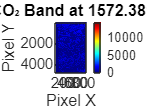

%% Identify CO₂ Absorption Bands
% Define the wavelength ranges for CO₂ absorption in NIR and SWIR regions (in nanometers)
co2_nir_range = [1570, 1610];  % Define the NIR CO₂ absorption range
co2_swir_range = [2000, 2060]; % Define the SWIR CO₂ absorption range

% Find the indices of the bands within the CO₂ absorption ranges
co2_nir_indices = find(hcube.Wavelength >= co2_nir_range(1) & hcube.Wavelength <= co2_nir_range(2));  % Find the NIR CO₂ band indices
co2_swir_indices = find(hcube.Wavelength >= co2_swir_range(1) & hcube.Wavelength <= co2_swir_range(2)); % Find the SWIR CO₂ band indices

% Display the indices of the CO₂ bands in the NIR and SWIR ranges
disp(['NIR CO₂ band indices: ', sprintf('%d ', co2_nir_indices)]);  % Display the indices of the NIR CO₂ bands
disp(['SWIR CO₂ band indices: ', sprintf('%d ', co2_swir_indices)]);  % Display the indices of the SWIR CO₂ bands

## Visualization Techniques

Image Display Functions:

Functions such as imagesc, colormap, and colorbar are used for visualizing extracted bands from hyperspectral data.

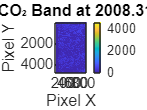

%% Extract and Visualize CO₂ Bands
% Visualize the first NIR CO₂ band if available
if ~isempty(co2_nir_indices)  % Check if there are any NIR CO₂ bands
    co2_nir_band = hcube.DataCube(:, :, co2_nir_indices(1));  % Extract the first NIR CO₂ band from the hypercube data
    figure;  % Create a new figure for displaying the band image
    imagesc(co2_nir_band);  % Display the NIR CO₂ band as an image (scale the values to fit the color range)
    colormap(jet);  % Use the 'jet' colormap to display the image in colorful shades
    colorbar;  % Add a color bar to the figure to indicate the intensity scale
    title(['NIR CO₂ Band at ', num2str(hcube.Wavelength(co2_nir_indices(1))), ' nm']);  % Set the title of the figure with the corresponding wavelength
    xlabel('Pixel X');  % Label the x-axis as 'Pixel X'
    ylabel('Pixel Y');  % Label the y-axis as 'Pixel Y'
end

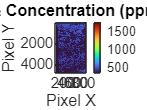


% Visualize the first SWIR CO₂ band if available
if ~isempty(co2_swir_indices)  % Check if there are any SWIR CO₂ bands
    co2_swir_band = hcube.DataCube(:, :, co2_swir_indices(1));  % Extract the first SWIR CO₂ band from the hypercube data
    figure;  % Create a new figure for displaying the band image
    imagesc(co2_swir_band);  % Display the SWIR CO₂ band as an image (scale the values to fit the color range)
    colormap(parula);  % Use the 'parula' colormap to display the image
    colorbar;  % Add a color bar to the figure to indicate the intensity scale
    title(['SWIR CO₂ Band at ', num2str(hcube.Wavelength(co2_swir_indices(1))), ' nm']);  % Set the title with the corresponding wavelength
    xlabel('Pixel X');  % Label the x-axis as 'Pixel X'
    ylabel('Pixel Y');  % Label the y-axis as 'Pixel Y'
end

## CO₂ Concentration Estimation

- Estimation Formula:CO Concentration ppm =(Band Reflectance×Scaling Factor)+OffsetCO Concentration ppm =(Band Reflectance×Scaling Factor)+Offset

- The images display the CO₂ absorption bands at specific wavelengths. 

- The NIR CO₂ band is shown first (around 1570-1610 nm), and the SWIR CO₂ band (around 2000-2060 nm) follows.

- These visualizations represent how the CO₂ concentration impacts the reflectance of light in those bands.

- Brighter areas typically indicate stronger absorption or higher CO₂ concentrations.

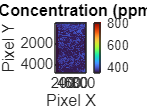

%% Estimate CO₂ Concentration
% Example calibration parameters for estimating CO₂ concentration from band data
scalingFactor = 0.1;  % Scaling factor to convert band reflectance values to CO₂ concentration
offset = 350;         % Baseline CO₂ concentration in ppm (parts per million)

% Convert the NIR CO₂ band to CO₂ concentration in ppm
if exist('co2_nir_band', 'var')  % Check if the NIR CO₂ band exists
    co2_nir_ppm = co2_nir_band * scalingFactor + offset;  % Convert NIR band values to CO₂ concentration in ppm
    figure;  % Create a new figure for displaying the CO₂ concentration map
    imagesc(co2_nir_ppm);  % Display the CO₂ concentration map as an image
    colormap(turbo);  % Use the 'turbo' colormap for better visual clarity of concentration variations
    colorbar;  % Add a color bar to the figure for interpreting the CO₂ concentration scale

    title('Estimated CO₂ Concentration (ppm) - NIR Band');  % Set the title of the figure
    xlabel('Pixel X');  % Label the x-axis as 'Pixel X'
    ylabel('Pixel Y');  % Label the y-axis as 'Pixel Y'
end

% Convert the SWIR CO₂ band to CO₂ concentration in ppm
if exist('co2_swir_band', 'var')  % Check if the SWIR CO₂ band exists
    co2_swir_ppm = co2_swir_band * scalingFactor + offset;  % Convert SWIR band values to CO₂ concentration in ppm
    figure;  % Create a new figure for displaying the CO₂ concentration map
    imagesc(co2_swir_ppm);  % Display the CO₂ concentration map as an image
    colormap(turbo);  % Use the 'turbo' colormap for clarity
    colorbar;  % Add a color bar to the figure
    title('Estimated CO₂ Concentration (ppm) - SWIR Band');  % Set the title of the figure

NIR CO₂ band image saved to co2_nir_band_image.mat


    xlabel('Pixel X');  % Label the x-axis as 'Pixel X'
    ylabel('Pixel Y');  % Label the y-axis as 'Pixel Y'
end

% Explanatory Notes for CO₂ Concentration Estimation:**
% The CO₂ concentration maps display the estimated concentration values based on the NIR and SWIR bands.

SWIR CO₂ band image saved to co2_swir_band_image.mat


% The scaling factor and offset are used to convert the reflectance values from the hyperspectral data into CO₂ concentration values in ppm.
% Higher intensity or brighter areas typically correspond to higher CO₂ concentrations in the image.

Processing complete.



%% Save CO₂ Band Images (Optional)
% Optionally, save the extracted CO₂ band images for later use or analysis
if exist('co2_nir_band', 'var')  % Check if the NIR CO₂ band exists
    outputNirFile = 'co2_nir_band_image.mat';  % Define the output file name for the NIR band image
    save(outputNirFile, 'co2_nir_band');  % Save the NIR CO₂ band to the .mat file
    disp(['NIR CO₂ band image saved to ', outputNirFile]);  % Display a message indicating the file has been saved
end

if exist('co2_swir_band', 'var')  % Check if the SWIR CO₂ band exists
    outputSwirFile = 'co2_swir_band_image.mat';  % Define the output file name for the SWIR band image
    save(outputSwirFile, 'co2_swir_band');  % Save the SWIR CO₂ band to the .mat file
    disp(['SWIR CO₂ band image saved to ', outputSwirFile]);  % Display a message indicating the file has been saved
end

disp('Processing complete.');  % Display a message indicating the processing is complete

